# Comparing Raw Data from StressLogger vs BioPac System

Hola.

% ---- Publication defaults (applies to this MATLAB session) ----
set(groot,'defaultFigureColor','w');

% Fonts & sizes (tweak to your journal)
set(groot,'defaultAxesFontName','Times', ...
          'defaultTextFontName','Times',  ...
          'defaultAxesFontSize',9, ...
          'defaultTextFontSize',9);

% Axes aesthetics
set(groot,'defaultAxesLineWidth',1, ...
          'defaultAxesTickDir','out', ...
          'defaultAxesBox','off', ...
          'defaultAxesXMinorTick','on', ...
          'defaultAxesYMinorTick','on', ...
          'defaultAxesXGrid','on', ...
          'defaultAxesYGrid','on', ...
          'defaultAxesGridAlpha',0.12, ...
          'defaultAxesMinorGridAlpha',0.08);

% Lines, markers, legends
set(groot,'defaultLineLineWidth',0.8, ...
          'defaultLineMarkerSize',5, ...
          'defaultLegendBox','off');

% (Optional) LaTeX text rendering — comment out if not using TeX
set(groot,'defaultTextInterpreter','latex', ...
          'defaultAxesTickLabelInterpreter','latex', ...
          'defaultLegendInterpreter','latex');


## ----------------------------------- Participant 8 -----------------------------------

Read data. Opts makes last column a 'char' variable

PID = 8;  % <-- change this FIRST %number of participant

opts = detectImportOptions("C:\Users\Lenovo\Desktop\Tesis\Data\MyDevice\Participante 8.csv", 'Delimiter', ',');
opts = setvartype(opts, 'phone_time', 'char');   

P1_BioPac = readtable("C:\Users\Lenovo\Desktop\Tesis\Data\BioPacSystem\Participante8.txt"); 
P1_MyDevice = readtable("C:\Users\Lenovo\Desktop\Tesis\Data\MyDevice\Participante 8.csv", opts);

Update the actual time of the Biopac Data, adding the stop/resumen interval

Manually change **TimeBio** and **TimeStop**


%Time Start BioPack = 15:16:08.655 + Resume Time: 00:00:19.290
    TimeBio = '15:16:08.655';
    TimeStop = '00:00:19.290';
    
    %Actual Start Time: 
    MilisToTime(TimeToMilis(TimeBio) + TimeToMilis(TimeStop))           

ans = '11:24:55:223'

Remove the rows from the start/resumen interval (s)

                      
TimeStopMilis = TimeToMilis(TimeStop);

P1_BioPac2 = P1_BioPac(TimeStopMilis+2:end, :); %%Start from the same part. delete before stop

Transform all (both files) to miliseconds from 0 to endtime

MilisToTime(P1_BioPac2.milliSec(end) - (P1_BioPac2.milliSec(1))) %%Their device total time

ans = '00:26:56:400'


MilisToTime( TimeToMilis(P1_MyDevice.phone_time{end}) - TimeToMilis(P1_MyDevice.phone_time{1}) ) %My device total time

ans = '00:26:56:380'

%Ideally both end times must be similar with less than 10s difference.
%CHECK THIS 
P1_MyDevice.phone_ms = cellfun(@TimeToMilis, P1_MyDevice.phone_time);
P1_MyDevice.phone_ms = P1_MyDevice.phone_ms - P1_MyDevice.phone_ms(1); %New variable with this. Use this one
P1_BioPac2.milliSec = P1_BioPac2.milliSec - P1_BioPac2.milliSec(1); % Make everything start from zero

Remove repeated values from biopac data

%% Remove Repeated values in P1_Biopac
t = P1_BioPac2.milliSec;
[~, idx_unique] = unique(t, 'stable');
P1_BioPac3 = P1_BioPac2(idx_unique, :);


Transform miliseconds to seconds

%% Transform All to seconds
t_bio = P1_BioPac3.milliSec/1000;
t_dev = P1_MyDevice.phone_ms/1000;

% Recalculate Skin Conductance
P1_MyDevice.EDA_V2 = EDA_adcToSkinConductance(P1_MyDevice.eda_adc);

Make a unique x-axis. **Adjust **the low-*value *to remove the drop from when de BioPac is disconected

T_end = min(t_bio(end), t_dev(end));

idx_bio = t_bio <= T_end;
idx_dev = t_dev <= T_end;

t_bio_c = t_bio(idx_bio);
t_dev_c = t_dev(idx_dev);

eda_bio = P1_BioPac3.CH5(idx_bio);


eda_dev = P1_MyDevice.EDA_V2(idx_dev); 

hr_bio = P1_BioPac3.CH40(idx_bio);
hr_dev = P1_MyDevice.HR(idx_dev);
% ADJUST THIS
thresh = 0.1;  
iLow = find(eda_bio < thresh, 1, 'first');

if ~isempty(iLow) && iLow > 1
  
    eda_bio = eda_bio(1:iLow-500); %Adjust the 35 to remove the big drop
    t_bio_c = t_bio_c(1:iLow-500);
    hr_bio  = hr_bio(1:iLow-500);  
end


**Graph the data** 

eda_bio_on_dev = interp1(t_bio_c, eda_bio, t_dev_c, 'linear'); %Resample
hr_bio_on_dev  = interp1(t_bio_c, hr_bio , t_dev_c, 'linear'); % <-- NEW: HR

%Remove cold press test
numNaN = sum(isnan(eda_bio_on_dev));
% EDA
eda_bio_on_dev = eda_bio_on_dev(1:end-numNaN);
t_bio_c        = t_bio_c(1:end-numNaN);
t_dev_c        = t_dev_c(1:end-numNaN);
eda_dev        = eda_dev(1:end-numNaN);

% HR 
hr_bio_on_dev  = hr_bio_on_dev(1:end-numNaN);
hr_dev         = hr_dev(1:end-numNaN);

#### HR Data cleaning

minHR = 30; %Adjust 
maxHR = 200; %Adjust as well

hr_bio_clean = hr_bio_on_dev;
hr_dev_clean = hr_dev;

winSamples = 51; 

rangeOutBio = hr_bio_clean < minHR | hr_bio_clean > maxHR;
rangeOutDev = hr_dev_clean < minHR | hr_dev_clean > maxHR;

movOutBio  = isoutlier(hr_bio_clean,'movmedian',winSamples);
movOutDev  = isoutlier(hr_dev_clean,'movmedian',winSamples);

badBio = rangeOutBio | movOutBio;
badDev = rangeOutDev | movOutDev;

hr_bio_clean(badBio) = NaN;
hr_dev_clean(badDev) = NaN;

hr_bio_clean = fillmissing(hr_bio_clean,'linear','EndValues','nearest');
hr_dev_clean = fillmissing(hr_dev_clean,'linear','EndValues','nearest');

% Make windows for BioPac HR

changeIdx = [1; find(diff(hr_dev_clean) ~= 0) + 1; numel(hr_dev_clean) + 1];

hr_bio_win = hr_bio_clean;  

for k = 1:numel(changeIdx)-1
    idxRange = changeIdx(k):changeIdx(k+1)-1;
        hr_bio_win(idxRange) = mean(hr_bio_clean(idxRange), 'omitnan');
end


(EDA)

% Now, lets plot my dog
fig = figure('Color','w','Renderer','painters');
plot(t_dev_c, eda_bio_on_dev, 'DisplayName', 'Biopac', Color="#EA4D49");
hold on;
plot(t_dev_c, eda_dev, 'DisplayName', 'Stress Logger', Color="#3F88C5");
xlabel('Time (s)');
ylabel('Skin conductance ($\mu S$)');
legend('Location','best');
grid on;
title(sprintf('Participant %d – EDA comparison', PID));

%Export Results
if ~exist('results','dir'); mkdir('results'); end

%Only .png bc pdf takes too long and I have to hand in this thesis next week

%exportgraphics(fig, fullfile('results', sprintf('EDA_P%d.pdf',PID)), ...
 %              'ContentType','vector');       
exportgraphics(fig, fullfile('results', sprintf('EDA_P%d.png',PID)), ...
               'Resolution',300);             

(HR)

fig = figure('Color','w','Renderer','painters');
plot(t_dev_c, hr_bio_win, 'DisplayName', 'Biopac', Color="#EA4D49");
hold on;
plot(t_dev_c, hr_dev_clean, 'DisplayName', 'Stress Logger', Color="#3F88C5");
xlabel('Time (s)');
ylabel('Heart rate (bpm)');
legend('Location','best');
grid on;
title(sprintf('Participant %d – HR comparison', PID));

% Export    

exportgraphics(fig, fullfile('results', sprintf('HR_P%d.png',PID)), ...
               'Resolution',300);             % optional PNG

**Calculate HRV only from HR intervals**

First define de Intervals (**CHANGE FOR EACH**)

t_rel = t_dev_c;   

% 0 - 0:33  Instruction reading (ignored)
PhaseNames = { ...
    'Relax 1', ...
    'Prep TSST', ...
    'TSST Speech', ...
    'Arithmetic', ...
    'Relax 2', ...
    'Stroop', ...
    'Relax 3'};

PhaseStart = [ ...
     33, ...   % Relax 1
    213, ...   % Prep TSST
    415, ...   % TSST Speech
    725, ...   % Arithmetic
    925, ...   % Relax 2
   1120, ...   % Stroop
   1180];      % Relax Last

PhaseEnd = [ ...
    213, ...   % Relax 1
    415, ...   % Prep TSST
    725, ...   % TSST Speech
    925, ...   % Arithmetic
   1120, ...   % Relax 2
   1180, ...   % Stroop
   1300];      % Relax Last (26:28)
%Change for each participant 

Now, lets compute HRV 

nPhase = numel(PhaseNames);


% HRV metrics
SDNN_BioPac  = nan(nPhase,1);
RMSSD_BioPac = nan(nPhase,1);
pNN50_BioPac = nan(nPhase,1);

SDNN_MyDev   = nan(nPhase,1);
RMSSD_MyDev  = nan(nPhase,1);
pNN50_MyDev  = nan(nPhase,1);

% NEW: mean HR per phase
meanHR_BioPac = nan(nPhase,1);
meanHR_MyDev  = nan(nPhase,1);

for p = 1:nPhase
    idx = t_rel >= PhaseStart(p) & t_rel < PhaseEnd(p);

    hr_seg_dev = hr_dev_clean(idx);
    hr_seg_bio = hr_bio_clean(idx);

    if sum(~isnan(hr_seg_dev)) < 5 || sum(~isnan(hr_seg_bio)) < 5
        continue;
    end

    % ---- mean HR (bpm) ----
    meanHR_MyDev(p)  = mean(hr_seg_dev, 'omitnan');
    meanHR_BioPac(p) = mean(hr_seg_bio, 'omitnan');

    % ---- HR -> RR [ms] ----
    RR_dev = 60000 ./ hr_seg_dev;
    RR_bio = 60000 ./ hr_seg_bio;

    RR_dev = RR_dev(~isnan(RR_dev));
    RR_bio = RR_bio(~isnan(RR_bio));

    if numel(RR_dev) < 5 || numel(RR_bio) < 5
        continue;
    end

    % ===== My Device =====
    SDNN_MyDev(p) = std(RR_dev, 0, 'omitnan');
    dRR_dev = diff(RR_dev);
    RMSSD_MyDev(p) = sqrt(mean(dRR_dev.^2, 'omitnan'));
    NN50_dev = sum(abs(dRR_dev) > 50);
    pNN50_MyDev(p) = 100 * NN50_dev / max(numel(dRR_dev),1);

    % ===== Biopac =====
    SDNN_BioPac(p) = std(RR_bio, 0, 'omitnan');
    dRR_bio = diff(RR_bio);
    RMSSD_BioPac(p) = sqrt(mean(dRR_bio.^2, 'omitnan'));
    NN50_bio = sum(abs(dRR_bio) > 50);
    pNN50_BioPac(p) = 100 * NN50_bio / max(numel(dRR_bio),1);
end



View table

Phase = PhaseNames';

HRV_P1 = table(Phase, ...
    meanHR_BioPac, meanHR_MyDev, ...
    SDNN_BioPac,   SDNN_MyDev, ...
    RMSSD_BioPac,  RMSSD_MyDev, ...
    pNN50_BioPac,  pNN50_MyDev);

disp(HRV_P1);

         Phase         meanHR_BioPac    meanHR_MyDev    SDNN_BioPac    SDNN_MyDev    RMSSD_BioPac    RMSSD_MyDev    pNN50_BioPac    pNN50_MyDev
    _______________    _____________    ____________    ___________    __________    ____________    ___________    ____________    ___________

    {'Relax 1'    }       84.757           83.555         58.192         31.141          7.262         2.6979         0.32617        0.096642  
    {'Prep TSST'  }       86.742           86.121         39.969         27.642         4.6007         1.9465         0.15991               0  
    {'TSST Speech'}       91.261           91.868         47.015         37.484         4.9073         1.9305        

Save this stuff my bro

%SAVE PHASE-LEVEL HRV FOR THIS PARTICIPANT

Participant = repmat(PID, height(HRV_P1), 1);
HRV_P1 = addvars(HRV_P1, Participant, 'Before', 'Phase');

if ~exist('results', 'dir')
    mkdir('results');
end

% File name results/HRV_P1.csv, HRV_P2.csv, ...
hrv_filename = fullfile('results', sprintf('HRV_P%d.csv', PID));

writetable(HRV_P1, hrv_filename);

#### HR Compare values

Pearson correlation. Error metrics (ME and MAE). Bland-Altman

%Pearson but for phases
valid = ~isnan(meanHR_BioPac) & ~isnan(meanHR_MyDev);
r_phase_HR = corr(meanHR_BioPac(valid), meanHR_MyDev(valid)) %use this one

r_phase_HR = 0.8066


% Keep only points where both are valid
valid = ~isnan(hr_bio_win) & ~isnan(hr_dev_clean);
x = hr_bio_win(valid);    % Biopac (reference)
y = hr_dev_clean(valid);    % Your device

% Pearson correlation
r_HR = corr(x, y)

r_HR = 0.2412




% Errors
err = y - x;
ME_HR  = mean(err)             % mean error (bias) [bpm]

ME_HR = 1.5158

MAE_HR = mean(abs(err))        % mean absolute error [bpm]

MAE_HR = 4.6996


% Bland–Altman numbers
bias_HR = ME_HR;
sd_err  = std(err);
LoA_low  = bias_HR - 1.96*sd_err;
LoA_high = bias_HR + 1.96*sd_err;


Bland-Altman Plot:

mean_xy = (x + y)/2;

fig = figure('Color','w','Renderer','painters');
scatter(mean_xy, err, 80, '.', MarkerEdgeColor='#136F63');
hold on;
yline(bias_HR,'-','Bias', Color='#EA4D49');
yline(LoA_low,'k--','+1.96 SD');
yline(LoA_high,'k--','-1.96 SD');
xlabel('Mean HR (bpm)');
ylabel('Difference (bpm)');
title(sprintf('Participant %d – Bland–Altman HR', PID));
grid on;
%Save this
%file1
    
exportgraphics(fig, fullfile('results', sprintf('BA_MeanHR_P%d.png',PID)), ...
               'Resolution',300); 

PIDcol = repmat(PID, numel(err), 1);
%file2
BA_HR = table(PIDcol, mean_xy(:), err(:), ...
    'VariableNames', {'Participant','MeanHR','DiffHR'});

writetable(BA_HR, fullfile('results', sprintf('BA_HR_P%d.csv', PID)));
%file3
BA_HR_summary = table(PID, bias_HR, LoA_low, LoA_high, ...
    'VariableNames', {'Participant','Bias_HR','LoA_low_HR','LoA_high_HR'});

writetable(BA_HR_summary, ...
    fullfile('results', sprintf('BA_HR_summary_P%d.csv', PID)));

#### HRV Comparsion

Pearson. Same error metrics as last. Interclass correlation coefficient (ICC). Bland-Altman but for the phases

### *[RMSSD]*

valid = ~isnan(RMSSD_BioPac) & ~isnan(RMSSD_MyDev);
x = RMSSD_BioPac(valid);
y = RMSSD_MyDev(valid);

% Pearson correlation
r_RMSSD = corr(x, y)

r_RMSSD = 0.6293


% Errors
err = y - x;
ME_RMSSD  = mean(err)

ME_RMSSD = -3.3290

MAE_RMSSD = mean(abs(err))

MAE_RMSSD = 3.3290



% Bland–Altman
bias_RMSSD = ME_RMSSD;
sd_err = std(err);
LoA_low_RMSSD  = bias_RMSSD - 1.96*sd_err;
LoA_high_RMSSD = bias_RMSSD + 1.96*sd_err;

Bland-Altman (**Should be for all participants at the same time**)

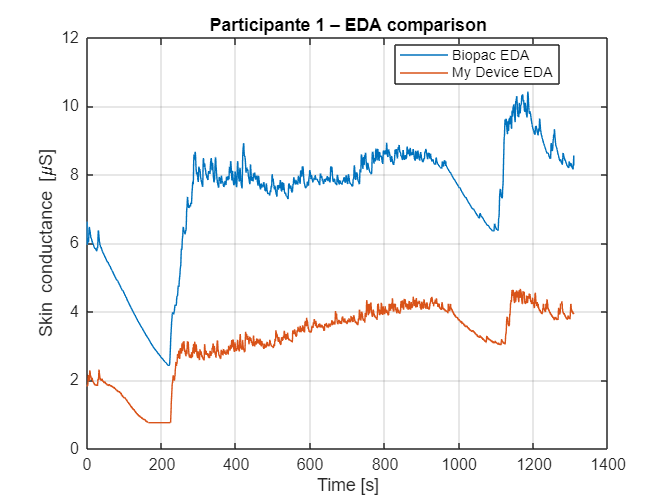

mean_xy = (x + y)/2;

fig = figure('Color','w','Renderer','painters');
scatter(mean_xy, err, 120, '.',MarkerEdgeColor='#136F63');
hold on;
yline(bias_RMSSD,'-','Bias', Color='#EA4D49');
yline(LoA_low_RMSSD,'k--','+1.96 SD');
yline(LoA_high_RMSSD,'k--','-1.96 SD');
xlabel('HRV RMSSD (ms)');
ylabel('Difference ');
title(sprintf('Participant %d – Bland–Altman HRV RMSSD', PID));
grid on;

%Save this
%file1
   
exportgraphics(fig, fullfile('results', sprintf('BA_RMSSD_P%d.png',PID)), ...
               'Resolution',300); 

PIDcol = repmat(PID, numel(err), 1);
%file2
BA_RMSSD = table(PIDcol, mean_xy(:), err(:), ...
    'VariableNames', {'Participant','RMSSD','DiffRMSSD'});

writetable(BA_RMSSD, fullfile('results', sprintf('BA_RMSSD_P%d.csv', PID)));
%file3
BA_RMSSD_summary = table(PID, bias_RMSSD, LoA_low_RMSSD, LoA_high_RMSSD, ...
    'VariableNames', {'Participant','Bias_RMSSD','LoA_low_RMSSD','LoA_high_RMSSD'});

writetable(BA_RMSSD_summary, ...
    fullfile('results', sprintf('BA_RMSSD_summary_P%d.csv', PID)));


### *[SDNN]*

valid = ~isnan(SDNN_BioPac) & ~isnan(SDNN_MyDev);
x = SDNN_BioPac(valid);
y = SDNN_MyDev(valid);


% Pearson correlation
r_SDNN = corr(x, y)

r_SDNN = 0.0583


% Errors
err = y - x;
ME_SDNN  = mean(err)

ME_SDNN = -19.8919

MAE_SDNN = mean(abs(err))

MAE_SDNN = 19.8919



% Bland–Altman
bias_SDNN = ME_SDNN;
sd_err = std(err);
LoA_low_SDNN  = bias_SDNN - 1.96*sd_err;
LoA_high_SDNN = bias_SDNN + 1.96*sd_err;

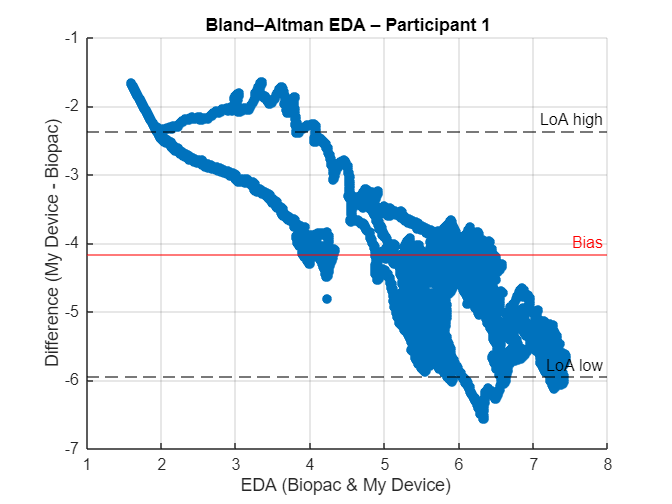

mean_xy = (x + y)/2; %Still for all participants


fig = figure('Color','w','Renderer','painters');
scatter(mean_xy, err, 120, '.',MarkerEdgeColor='#136F63');
hold on;
yline(bias_SDNN,'-','Bias', Color='#EA4D49');
yline(LoA_low_SDNN,'k--','+1.96 SD');
yline(LoA_high_SDNN,'k--','-1.96 SD');
xlabel('HRV SDNN (ms)');
ylabel('Difference ');
title(sprintf('Participant %d – Bland–Altman HRV SDNN', PID));
grid on;
%Save this
%file1
  
exportgraphics(fig, fullfile('results', sprintf('BA_SDNN_P%d.png',PID)), ...
               'Resolution',300); 

PIDcol = repmat(PID, numel(err), 1);
%file2
BA_SDNN = table(PIDcol, mean_xy(:), err(:), ...
    'VariableNames', {'Participant','SDNN','DiffSDNN'});

writetable(BA_SDNN, fullfile('results', sprintf('BA_SDNN_P%d.csv', PID)));
%file3
BA_SDNN_summary = table(PID, bias_SDNN, LoA_low_SDNN, LoA_high_SDNN, ...
    'VariableNames', {'Participant','Bias_SDNN','LoA_low_SDNN','LoA_high_SDNN'});

writetable(BA_SDNN_summary, ...
    fullfile('results', sprintf('BA_SDNN_summary_P%d.csv', PID)));

ICC for RMSS and SDNN

valid = ~isnan(RMSSD_BioPac) & ~isnan(RMSSD_MyDev);
icc_RMSSD = icc_two_devices(RMSSD_BioPac(valid), RMSSD_MyDev(valid))

icc_RMSSD = 0.0662


valid = ~isnan(SDNN_BioPac) & ~isnan(SDNN_MyDev);
icc_SDNN = icc_two_devices(SDNN_BioPac(valid), SDNN_MyDev(valid))

icc_SDNN = 0.0147

#### EDA Comparison 

valid = ~isnan(eda_bio_on_dev) & ~isnan(eda_dev);
x = eda_bio_on_dev(valid);   % Biopac
y = eda_dev(valid);          % My device

r_EDA = corr(x, y)

r_EDA = -0.1483


err = y - x;
ME_EDA  = mean(err)

ME_EDA = -0.0823

MAE_EDA = mean(abs(err))

MAE_EDA = 0.5466

% Bland–Altman EDA
bias_EDA = ME_EDA;
sd_err = std(err);
LoA_low_EDA  = bias_EDA - 1.96*sd_err;
LoA_high_EDA = bias_EDA + 1.96*sd_err;

Graph Bland-Altman

mean_xy = (x + y)/2;

fig = figure('Color','w','Renderer','painters');
scatter(mean_xy, err, 60,'.',MarkerEdgeColor='#136F63');
hold on;
yline(bias_EDA,'-','Bias', Color='#EA4D49');
yline(LoA_low_EDA,'k--','+1.96 SD');
yline(LoA_high_EDA,'k--','-1.96 SD');
xlabel('EDA ($\mu S$) ');
ylabel('Difference');
title(sprintf('Participant %d – Bland–Altman EDA', PID));
grid on;

  
exportgraphics(fig, fullfile('results', sprintf('BA_EDA_P%d.png',PID)), ...
               'Resolution',300); 

PIDcol = repmat(PID, numel(err), 1);
%file2
BA_EDA = table(PIDcol, mean_xy(:), err(:), ...
    'VariableNames', {'Participant','EDA','DiffEDA'});

writetable(BA_EDA, fullfile('results', sprintf('BA_EDA_P%d.csv', PID)));
%file3
BA_EDA_summary = table(PID, bias_EDA, LoA_low_EDA, LoA_high_EDA, ...
    'VariableNames', {'Participant','Bias_EDA','LoA_low_EDA','LoA_high_EDA'});

writetable(BA_EDA_summary, ...
    fullfile('results', sprintf('BA_EDA_summary_P%d.csv', PID)));

### Save all (finally)

Summary_PID = table( ...
    PID, ...
    r_HR, ME_HR, MAE_HR, ...
    r_EDA, ME_EDA, MAE_EDA, ...
    r_SDNN, ME_SDNN, MAE_SDNN, icc_SDNN, ...
    r_RMSSD, ME_RMSSD, MAE_RMSSD, icc_RMSSD ,r_phase_HR, ...
    'VariableNames', { ...
        'PID', ...
        'r_HR','ME_HR','MAE_HR', ...
        'r_EDA','ME_EDA','MAE_EDA', ...
        'r_SDNN','ME_SDNN','MAE_SDNN','icc_SDNN', ...
        'r_RMSSD','ME_RMSSD','MAE_RMSSD','icc_RMSSD', 'r_phase_HR'});

summary_filename = fullfile('results', sprintf('Summary_P%d.csv', PID));

writetable(Summary_PID, summary_filename);

# Functions:

% ////////////////////////////////////////////////// %
%% ////////////////////Functions//////////////////// %%
% ////////////////////////////////////////////////// %
function Milis = TimeToMilis(Time)
%%'00:00:00:000'
HH = str2double(Time(1:2));
MM = str2double(Time(4:5));
SS = str2double(Time(7:8));
MS = str2double(Time(10:12));
Milis = HH*3600000 + MM*60000 + SS*1000 + MS;
end 

function Time = MilisToTime(Milis)
    %%Input Milis Output String: '00:00:00:000'
    HH = floor(Milis / 3600000);
    Milis = mod(Milis, 3600000);
    MM = floor(Milis / 60000);
    Milis = mod(Milis, 60000);
    SS = floor(Milis / 1000);
    Milis = mod(Milis, 1000);
    MS = round(Milis);
    Time = sprintf('%02d:%02d:%02d:%03d', HH, MM, SS, MS);
end

function CSkin = EDA_adcToSkinConductance(EDAADC)
    R   = 190000;   % Ohm
    F   = 4450;     % Ohm
    VCC = 1.94;      % V
    Vout  = (double(EDAADC) * 3.3) / 4095;                 
    Rskin = (R * (Vout .* (R + F) + 2*VCC*F)) ./ (2*VCC*R - Vout.*R - Vout.*F);                 
    CSkin = zeros(size(Rskin));                            
    idx = Rskin > 0;
    CSkin(idx) = 1e6 ./ Rskin(idx);                        
end

function icc_val = icc_two_devices(x, y)
% x and y are column vectors (e.g. Biopac, MyDevice) of same length

data = [x(:) y(:)];   % n x 2 matrix
[n, k] = size(data);  % k = 2 devices

% Remove any rows with NaNs in either device
data = data(all(~isnan(data),2),:);
[n, k] = size(data);
if n < 2
    icc_val = NaN;
    return;
end
% Means
mean_rows = mean(data,2);
mean_cols = mean(data,1);
grand_mean = mean(data(:));

% Sum of squares
SSR = k * sum((mean_rows - grand_mean).^2);          % rows (targets)
SSC = n * sum((mean_cols - grand_mean).^2);          % cols (devices)
SSE = sum(sum((data - mean_rows - mean_cols + grand_mean).^2));

MSR = SSR / (n-1);
MSC = SSC / (k-1);
MSE = SSE / ((n-1)*(k-1));

% ICC(2,1): two-way random, absolute agreement
icc_val = (MSR - MSE) / (MSR + (k-1)*MSE + k*(MSC - MSE)/n);
end

% ////////////////////////////////////////////////// %
%% ///////////////////////////////////////////////// %%
% ////////////////////////////////////////////////// 